clc; close all; clear;

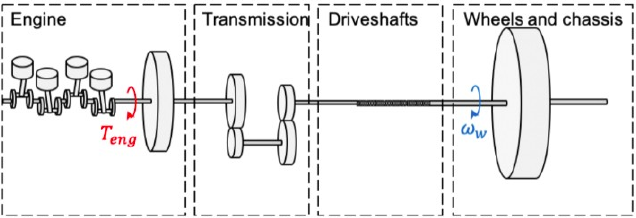

Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
GR = 57; % gear ratio

A  = [-ds/(Jf*GR^2) ds/(Jf*GR) -cs/(Jf*GR)
       ds/(Jc*GR)  -ds/(Jc)    cs/Jc
        1/GR           -1         0         ];
Bu = [1/Jf 0  0]';
Bd = [0 -1/Jc 0]';
C  = [0   1   0];

### Encuentre la matriz de observabilidad. ¿Es el sistema observable?

if (rank([C;C*A;C*A*A]) == 3)
    disp('El sistema es completamente observable desde la velocidad en las ruedas.')
else
    disp('El sistema no es completamente observable desde la velocidad en las ruedas.')
end

El sistema es completamente observable desde la velocidad en las ruedas.


### Verifique si el sistema es observable para C=[1 0 0] , C=[0 1 0] y C=[0 0 1].

C = [1 0 0];
if (rank([C;C*A;C*A*A]) == 3)
    disp('El sistema es completamente observable desde la velocidad en el motor.')
else
    disp('El sistema no es completamente observable desde la velocidad en el motor.')
end

El sistema es completamente observable desde la velocidad en el motor.



C = [0 0 1];
if (rank([C;C*A;C*A*A]) == 3)
    disp('El sistema es completamente observable desde el torque en el motor.')
else
    disp('El sistema no es completamente observable desde el torque en el motor.')
end

El sistema no es completamente observable desde el torque en el motor.


### Luego de analizar los 3 escenarios posibles de observabilidad, ¿qué sensor o sensores de salida elegiría para este sistema?

Un sensor de velocidad del motor es mas práctico que un sensor de la velocidad de las ruedas. Así que utilizaría un sensor de velocidad del motor.